data = readtable("identificare_sistem.csv")

data = 200×3 table
    time    pwm    rpm
    ____    ___    ___

    0.05     0      0 
     0.1     0      0 
    0.15     0      0 
     0.2     0      0 
    0.25     0      0 
     0.3     0      0 
    0.35     0      0 
     0.4     0      0 
    0.45     0      0 
     0.5     0      0 
    0.55     0      0 
     0.6     0      0 
    0.65     0      0 
     0.7     0      0 
    0.75     0      0 
     0.8     0      0 


t = data.time;
u = data.pwm;
y = data.rpm;

Ts = mean(diff(t))

Ts = 0.0500

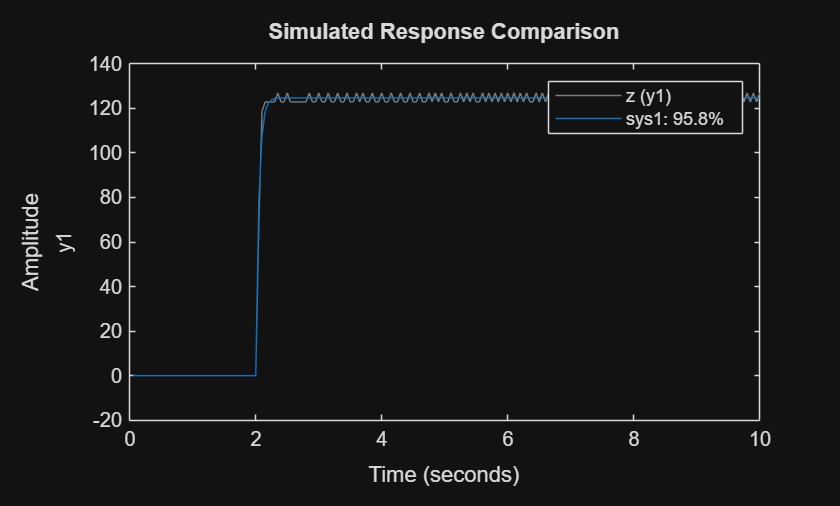


z = iddata(y, u, Ts);

sys1 = procest(z, "P1");
compare(z, sys1)

tf(sys1)


ans =
 
  From input "u1" to output "y1":
     0.8311
  -------------
  0.04964 s + 1
 
Continuous-time transfer function.
